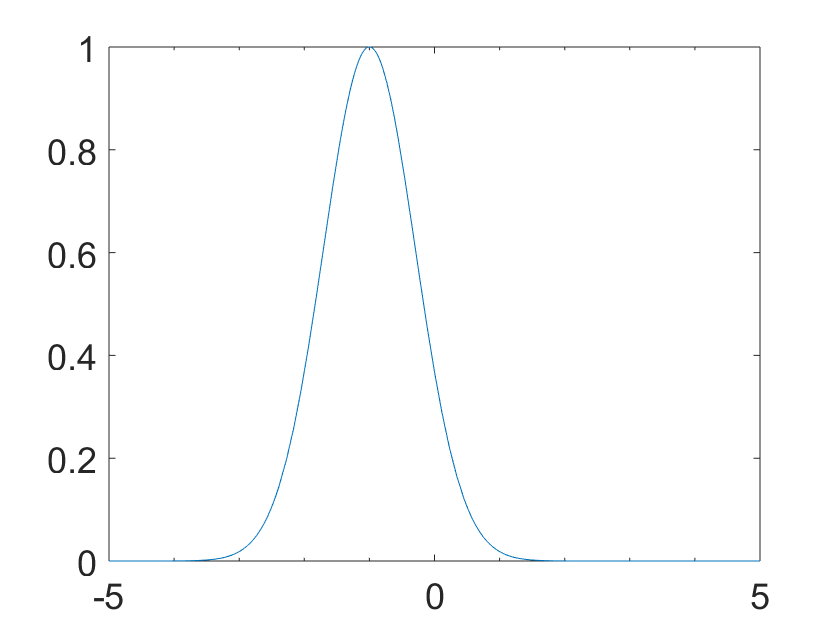

x0=1;
gaus = @(x) exp(-(x+x0)^2);
fplot(gaus)

a = test_script;
a.Value = pi/3

a =   test_script with properties:

    Value: 1.0472


a.roundOff

ans = 1.0500

roundOff(a)

ans = 1.0500

a.multRound(3)

ans = 3.1500

sigma = @(x0,T0) 1/sqrt(pi)*integral(@(u)exp(-u^2)*tanh((delta0(i)*u+lambda*x0)./T0),-inf,inf,'ArrayValued',true)-x0

sigma = function_handle with value:
    @(x0,T0)1/sqrt(pi)*integral(@(u)exp(-u^2)*tanh((delta0(i)*u+lambda*x0)./T0),-inf,inf,'ArrayValued',true)-x0


sz = @(T) fzero(@(x)sigma(x,T),[1e-3 1])

sz = function_handle with value:
    @(T)fzero(@(x)sigma(x,T),[1e-3,1])


sz(1e-2)

ans = 0.7727

sz(2.25)

ans = 0.2941

syms x T u
% f=@(x,T) x^3+3*x+1+T
sigma1 = @(x,T) 1/sqrt(pi)*int(exp(-u^2)*tanh((delta0(i)*u+lambda*x)./T),u,[-inf,inf])-x

sigma1 = function_handle with value:
    @(x,T)1/sqrt(pi)*int(exp(-u^2)*tanh((delta0(i)*u+lambda*x)./T),u,[-inf,inf])-x


sigma1(1,1)

$$ans = \frac{5081767996463981\,\int_{-\infty }^{\infty }\tanh\left(\frac{8967928672568529\,u}{2251799813685248}+\frac{22}{5}\right)\,{\mathrm{e}}^{-u^{2}}\mathrm{d}u}{9007199254740992}-1$$

sigma2 = matlabFunction(sigma1(x,T))

sigma2 = function_handle with value:
    @(T,x)-x+integral(@(u)tanh((u.*3.982560358192679+x.*(2.2e1./5.0))./T).*exp(-u.^2),-Inf,Inf).*5.641895835477563e-1


% gfun=diff(f(x,T),T)
dsigma = diff(sigma1(x,T),x)

$$dsigma = \frac{5081767996463981\,\int_{-\infty }^{\infty }\left(-\frac{22\,{\mathrm{e}}^{-u^{2}}\,\left({\tanh\left(\frac{\frac{8967928672568529\,u}{2251799813685248}+\frac{22\,x}{5}}{T}\right)}^{2}-1\right)}{5\,T}\right)\mathrm{d}u}{9007199254740992}-1$$

g = matlabFunction(dsigma)

g = function_handle with value:
    @(T,x)integral(@(u)(exp(-u.^2).*(tanh((u.*3.982560358192679+x.*(2.2e1./5.0))./T).^2-1.0).*(-2.2e1./5.0))./T,-Inf,Inf).*5.641895835477563e-1-1.0


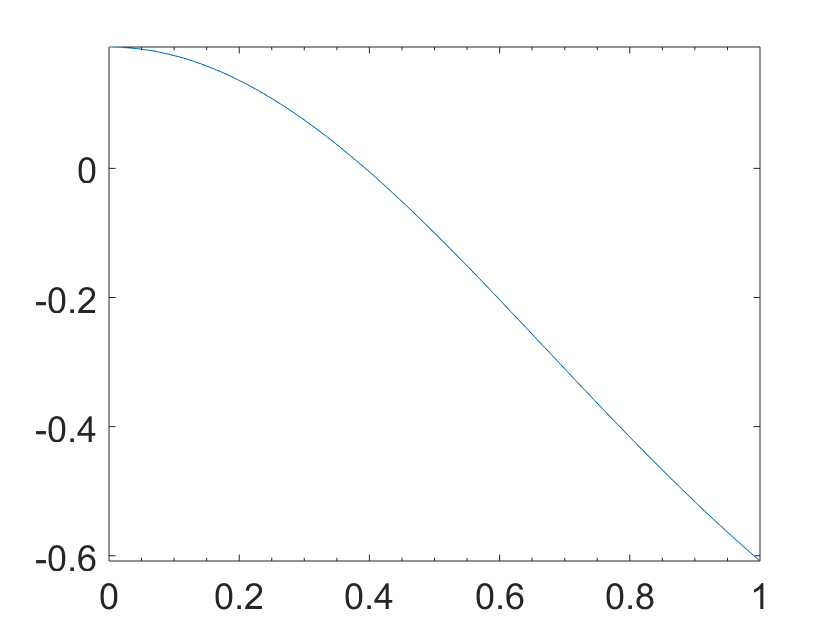

fplot(@(x)g(1,x),[0 1])

g(1,0.39)

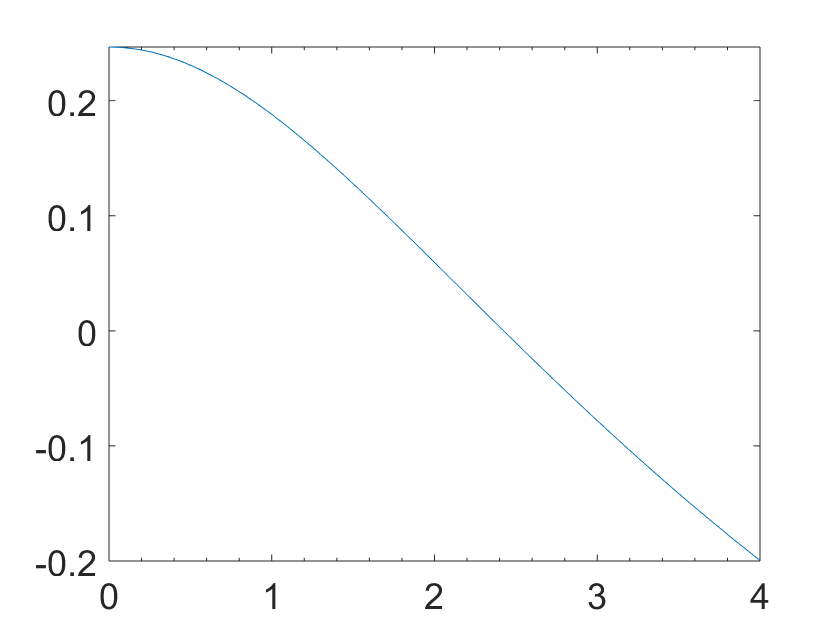

fplot(@(T)g(T,0),[0 4])

g(1e-3,0)

ans = 0.2467

maxT = fzero(@(T)g(T,0),[1e-3 4])

maxT = 2.4246

fic = @(a,b,R,x) a/2*((1-R)*(a*x).^2*exp(-a.*x)+2*R*(a^2*b)/(a-b)^3).*heaviside(x)

fic = function_handle with value:
    @(a,b,R,x)a/2*((1-R)*(a*x).^2*exp(-a.*x)+2*R*(a^2*b)/(a-b)^3).*heaviside(x)


fpv = @(I,mu,w,xc,x) I*(mu*(2/pi)*(w./(4*(x-xc).^2 + w^2)) + (1 - mu)*(sqrt(4*log(2))/(sqrt(pi)*w))*exp(-(4*log(2)/w^2).*(x-xc).^2))

fpv = function_handle with value:
    @(I,mu,w,xc,x)I*(mu*(2/pi)*(w./(4*(x-xc).^2+w^2))+(1-mu)*(sqrt(4*log(2))/(sqrt(pi)*w))*exp(-(4*log(2)/w^2).*(x-xc).^2))


fic1 = @(x) fic(2,0.5 ,0.1,x)

fic1 = function_handle with value:
    @(x)fic(2,0.5,0.1,x)


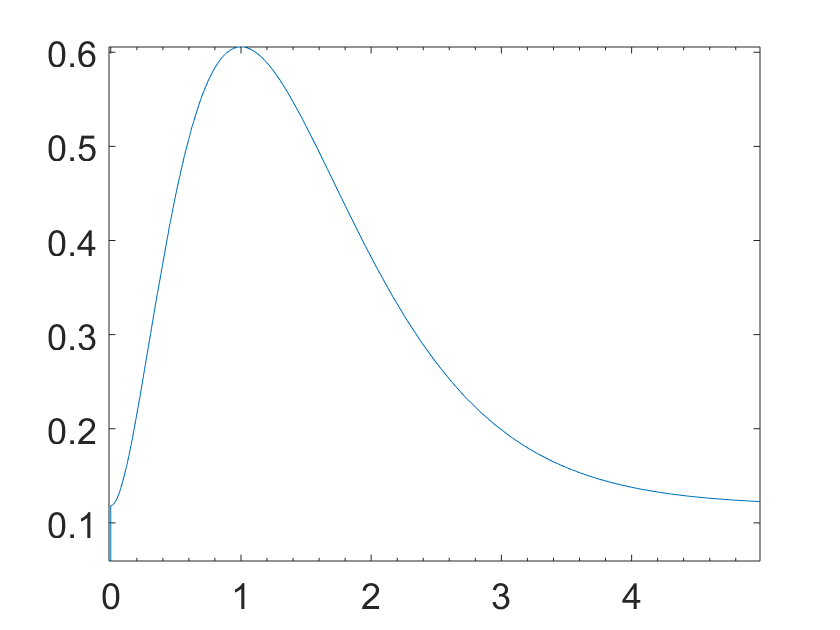

fplot(fic1,[0 5])

fpv1 = @(x) fpv(1,0.5,1,0,x)

fpv1 = function_handle with value:
    @(x)fpv(1,0.5,1,0,x)


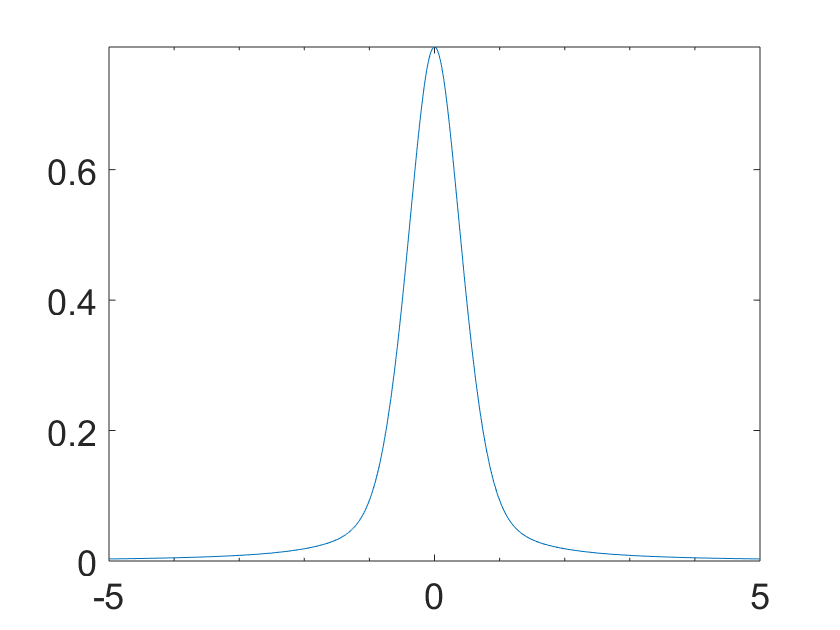

fplot(fpv1)

x1 = 0:0.1:5

x1 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


conv(fic1(x1),fpv1(x1),'same')

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in test>@(a,b,R,x)a/2*((1-R)*(a*x).^2*exp(-a.*x)+2*R*(a^2*b)/(a-b)^3).*heaviside(x)

Error in test>@(x)fic(2,0.5,0.1,x)

syms x t
ficpv = simplify(ifourier(fourier(fic1,x,t)*fourier(fpv1,x,t),t,x))

$$ficpv = \begin{array}{l} \frac{\frac{\pi \,\left(11933390974516242042249610556527\,\pi +189284997021418798448640\,\sqrt{2}\,\sqrt{6243314768165359}\,\sqrt{\pi }\right)}{632641276427990071839013931581440}+\frac{51607450253003931\,\pi \,\left(\mathrm{fourier}\left(\frac{{\mathrm{e}}^{-\frac{t}{2}}\,\mathrm{heaviside}\left(t\right)}{\sigma_{1}},t,-x\right)+\mathrm{fourier}\left(\frac{\mathrm{heaviside}\left(-t\right)\,{\mathrm{e}}^{t/2}}{\sigma_{1}},t,-x\right)\right)}{45035996273704960}+\frac{1911387046407553\,\pi \,\mathrm{atan}\left(2\,x\right)}{50665495807918080}-\frac{188037750146209\,\sqrt{2}\,\sqrt{6243314768165359}\,\sqrt{\pi }\,\mathrm{fourier}\left(\frac{\sigma_{2}}{t},t,-x\right)\,\mathrm{i}}{628472642529000909963264}+\frac{15231057761842929\,\sqrt{2}\,\sqrt{6243314768165359}\,\sqrt{\pi }\,\mathrm{fourier}\left(\frac{\sigma_{2}}{\sigma_{1}},t,-x\right)}{837963523372001213284352}}{2\,\pi }\\ \mathrm{where}\\ \sigma_{1}=-t^{3}\,\mathrm{i}-6\,t^{2}+12\,t\,\mathrm{i}+8\\ \sigma_{2}={\mathrm{e}}^{-\frac{562949953421312\,t^{2}}{6243314768165359}} \end{array}$$

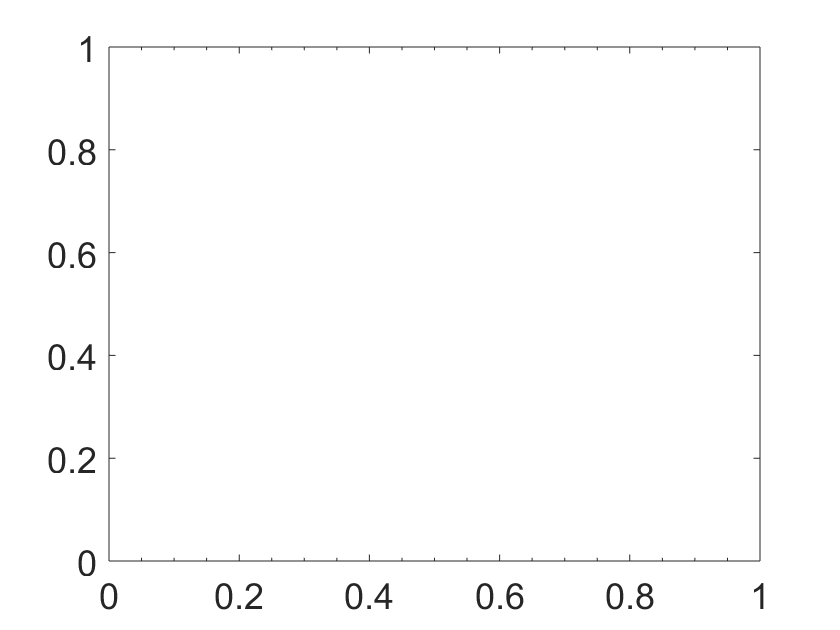

fplot(ficpv)